## **SE 267A HW3**

% Initialization and default plot settings.
clc; 
clear; 
close all; 

set(0, 'DefaultAxesFontSize', 15);
set(0, 'DefaultTextFontSize', 15);
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

### **Problem 1**

**Plot the analog signal and the sampled signal:**

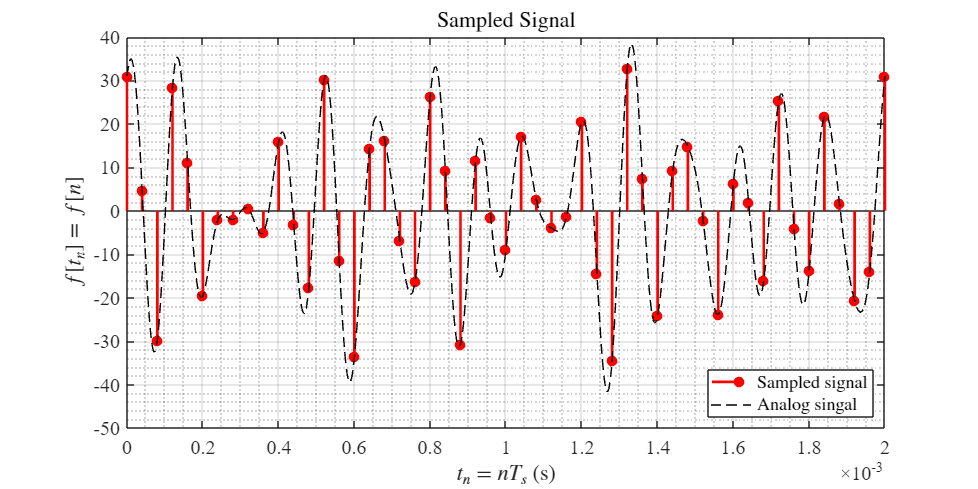

% Create a fine time vector and calculate the data points for analog signal plot.
AnalogTimeVector = 0:(1/1000000):0.002;
AnalogSignal = cos(2000*pi*AnalogTimeVector) + 5*sin(6000*pi*AnalogTimeVector) + 10*cos(12000*pi*AnalogTimeVector) + 20*cos(15000*pi*AnalogTimeVector) + 10*sin(20000*pi*AnalogTimeVector);

% Create the sampled time vector and calculate the sampled discrete signal.
f_s = 25000; % fs = Sampling rate.
SampledTimeVector = 0:(1/f_s):0.002;
SampledSignal = cos(2000*pi*SampledTimeVector) + 5*sin(6000*pi*SampledTimeVector) + 10*cos(12000*pi*SampledTimeVector) + 20*cos(15000*pi*SampledTimeVector) + 10*sin(20000*pi*SampledTimeVector);

% Plot the analog signal and the sampled signal.
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(SampledTimeVector, SampledSignal, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
plot(AnalogTimeVector, AnalogSignal, '--k');
grid on;
grid minor;
box on;
xlabel('$t_n=nT_s$ (s)', 'Interpreter', 'latex');
ylabel('$f[t_n]=f[n]$', 'Interpreter', 'latex');
legend('Sampled signal', 'Analog singal', 'Interpreter', 'latex', 'Location', 'southeast');
title('Sampled Signal', 'Interpreter', 'latex');

**Calculate the number of samples *****L***** in the sampled signal *****f*****[*****n*****]:**

% Calculate the number of samples L in the sampled signal f[n].
L = length(SampledSignal)

L = 51

### Problem 2

**Case 1: Discretize the frequency based on the true periodicity (*****N***** = 50)**

% Given the fundamental period of the signal.
Tp = 0.002;

% Calculate the periodicity N of the signal.
N = Tp / (1/f_s);

% Create the sample index vector and calculate the frequency components.
k1 = 0:1:(N-1); % k = Sample index vector.
omega_k1 = (2*pi/N) * k1; % omega_k = Angular frequency.
f_k1 = omega_k1 / (2*pi) * f_s; % f_k = Discretized frequency in Hertz.

% Display the discretized frequency components.
display(omega_k1);

omega_k1 =          0    0.1257    0.2513    0.3770    0.5027    0.6283    0.7540    0.8796    1.0053    1.1310    1.2566    1.3823    1.5080    1.6336    1.7593    1.8850    2.0106    2.1363    2.2619    2.3876    2.5133    2.6389    2.7646    2.8903    3.0159    3.1416    3.2673    3.3929    3.5186    3.6442    3.7699    3.8956    4.0212    4.1469    4.2726    4.3982    4.5239    4.6496    4.7752    4.9009    5.0265    5.1522    5.2779    5.4035    5.5292    5.6549    5.7805    5.9062    6.0319    6.1575


**Discretized angular frequency components:**

0	0.1257	0.2513	0.3770	0.5027	0.6283	0.7540	0.8796	1.0053	1.1310	1.2566	1.3823	1.5080	1.6336	1.7593	1.8850	2.0106	2.1363	2.2619	2.3876	2.5133	2.6389	2.7646	2.8903	3.0159	3.1416	3.2673	3.3929	3.5186	3.6442	3.7699	3.8956	4.0212	4.1469	4.2726	4.3982	4.5239	4.6496	4.7752	4.9009	5.0265	5.1522	5.2779	5.4035	5.5292	5.6549	5.7805	5.9062	6.0319	6.1575

disp(f_k1);

   1.0e+04 *

         0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500



**Discretized frequency components in 10^4 Hz:**

`0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500`

**Case 2: Discretize the frequency based on the number of samples (*****N***** = 51)**

% Create the sample index vector and calculate the frequency components.
k2 = 0:1:(L-1); % k = Sample index vector.
omega_k2 = (2*pi/L) * k2; % omega_k = Angular frequency.
f_k2 = omega_k2 / (2*pi) * f_s; % f_k = Discretized frequency in Hertz.

% Display the discretized frequency components.
display(omega_k2);

omega_k2 =          0    0.1232    0.2464    0.3696    0.4928    0.6160    0.7392    0.8624    0.9856    1.1088    1.2320    1.3552    1.4784    1.6016    1.7248    1.8480    1.9712    2.0944    2.2176    2.3408    2.4640    2.5872    2.7104    2.8336    2.9568    3.0800    3.2032    3.3264    3.4496    3.5728    3.6960    3.8192    3.9424    4.0656    4.1888    4.3120    4.4352    4.5584    4.6816    4.8048    4.9280    5.0512    5.1744    5.2976    5.4208    5.5440    5.6672    5.7904    5.9136    6.0368


**Discretized angular frequency components:**

0	0.1232	0.2464	0.3696	0.4928	0.6160	0.7392	0.8624	0.9856	1.1088	1.2320	1.3552	1.4784	1.6016	1.7248	1.8480	1.9712	2.0944	2.2176	2.3408	2.4640	2.5872	2.7104	2.8336	2.9568	3.0800	3.2032	3.3264	3.4496	3.5728	3.6960	3.8192	3.9424	4.0656	4.1888	4.3120	4.4352	4.5584	4.6816	4.8048	4.9280	5.0512	5.1744	5.2976	5.4208	5.5440	5.6672	5.7904	5.9136	6.0368	6.1600

disp(f_k2);

   1.0e+04 *

         0    0.0490    0.0980    0.1471    0.1961    0.2451    0.2941    0.3431    0.3922    0.4412    0.4902    0.5392    0.5882    0.6373    0.6863    0.7353    0.7843    0.8333    0.8824    0.9314    0.9804    1.0294    1.0784    1.1275    1.1765    1.2255    1.2745    1.3235    1.3725    1.4216    1.4706    1.5196    1.5686    1.6176    1.6667    1.7157    1.7647    1.8137    1.8627    1.9118    1.9608    2.0098    2.0588    2.1078    2.1569    2.2059    2.2549    2.3039    2.3529    2.4020    2.4510



**Discretized frequency components in 10^4 Hz:**

`0    0.0490    0.0980    0.1471    0.1961    0.2451    0.2941    0.3431    0.3922    0.4412    0.4902    0.5392    0.5882    0.6373    0.6863    0.7353    0.7843    0.8333    0.8824    0.9314    0.9804    1.0294    1.0784    1.1275    1.1765    1.2255    1.2745    1.3235    1.3725    1.4216    1.4706    1.5196    1.5686    1.6176    1.6667    1.7157    1.7647    1.8137    1.8627    1.9118    1.9608    2.0098    2.0588    2.1078    2.1569    2.2059    2.2549    2.3039    2.3529    2.4020    2.4510`

### Problem 3

**Case 1: Discretize the frequency based on the true periodicity (*****N***** = 50)**

% Initialization for the DTFS Fourier coefficient vector.
F_k1 = zeros(1,N);

% Calculate each DTFS Fourier coefficient component.
for k = 0:N-1 
    for m = 0:N-1
        F_k1(k+1) = F_k1(k+1) + SampledSignal(m+1) * exp(-1i*omega_k1(k+1)*m);
    end
end

F_k1 = F_k1/N;

% Calculate the magnitude and phase of Fourier coefficients.
F_k1_magnitude = abs(F_k1);
F_k1_phase = angle(F_k1);


**Case 2: Discretize the frequency based on the number of samples (*****N***** = 51)**

% Initialization for the DTFS Fourier coefficient vector.
F_k2 = zeros(1,L);

% Calculate each DTFS Fourier coefficient component.
for k = 0:L-1 
    for m = 0:L-1
        F_k2(k+1) = F_k2(k+1) + SampledSignal(m+1) * exp(-1i*omega_k2(k+1)*m);
    end
end

F_k2 = F_k2/L;

% Calculate the magnitude and phase of Fourier coefficients.
F_k2_magnitude = abs(F_k2);
F_k2_phase = angle(F_k2);

**Plot the results:**

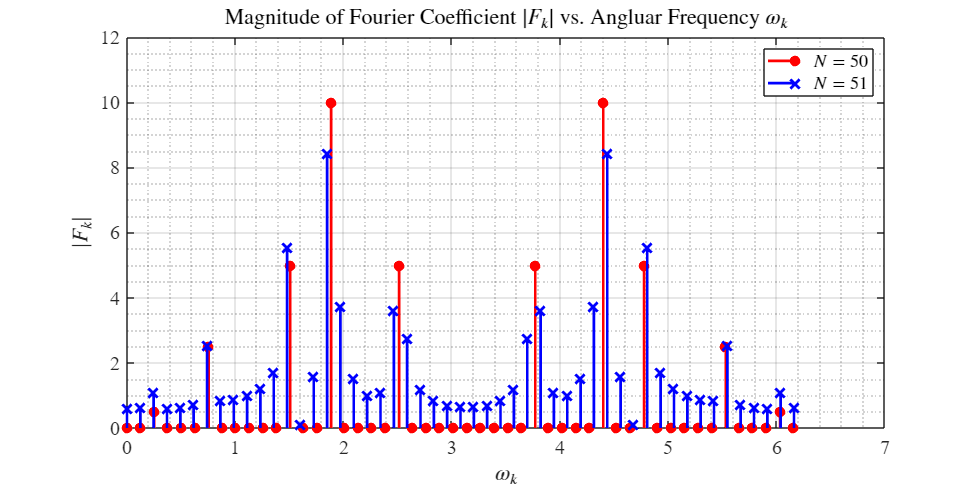

% Plot magnitude vs angular frequency.
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(omega_k1, F_k1_magnitude, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(omega_k2, F_k2_magnitude, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'b', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega_k$', 'Interpreter', 'latex');
ylabel('$|F_k|$', 'Interpreter', 'latex');
legend('$N = 50$', '$N = 51$', 'Interpreter', 'latex', 'Location', 'northeast');
title('Magnitude of Fourier Coefficient $|F_k|$ vs. Angluar Frequency $\omega_k$', 'Interpreter', 'latex');

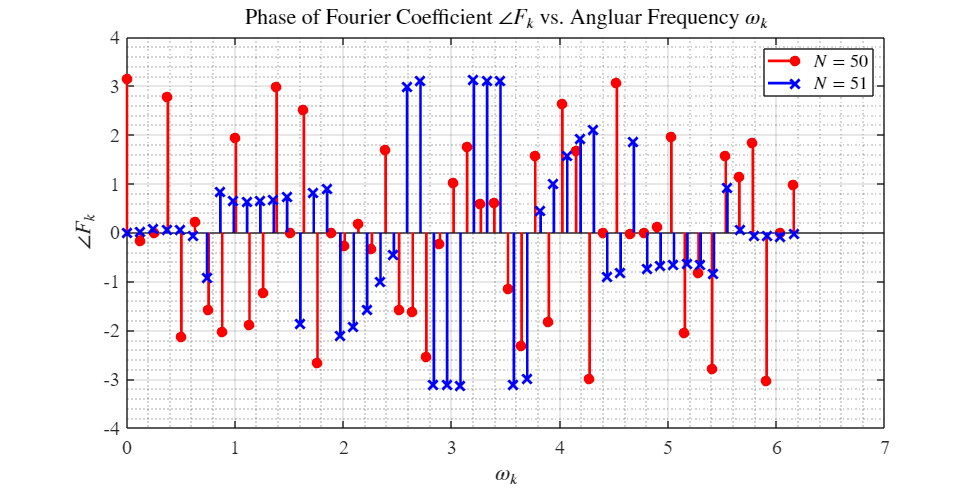

% Plot phase vs angular frequency.
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(omega_k1, F_k1_phase, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(omega_k2, F_k2_phase, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'b', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega_k$', 'Interpreter', 'latex');
ylabel('$\angle F_k$', 'Interpreter', 'latex');
legend('$N = 50$', '$N = 51$', 'Interpreter', 'latex', 'Location', 'northeast');
title('Phase of Fourier Coefficient $\angle F_k$ vs. Angluar Frequency $\omega_k$', 'Interpreter', 'latex');

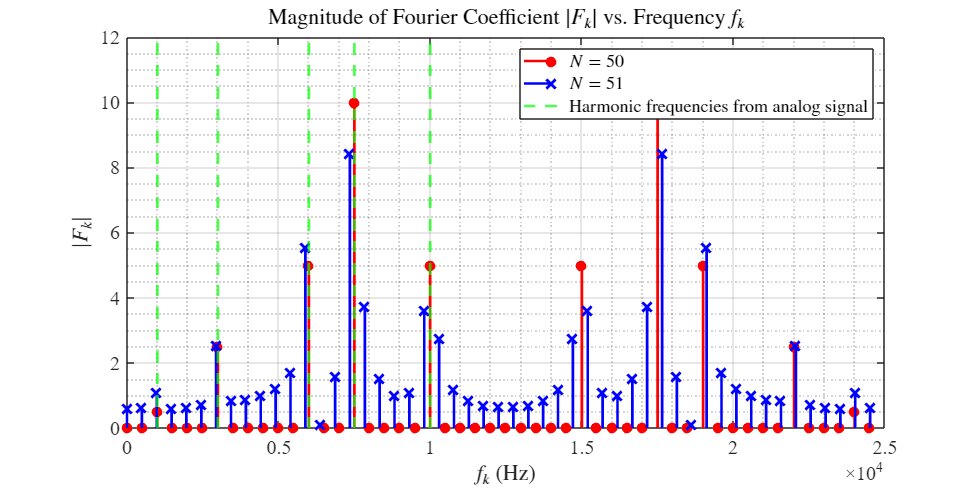

% Plot magnitude vs frequency (Hz).
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(f_k1, F_k1_magnitude, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(f_k2, F_k2_magnitude, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'b', 'LineWidth', 2);

harmonic_frequency = [1000, 3000, 6000, 7500, 10000];
xline(harmonic_frequency, 'g--', 'LineWidth', 2);

grid on;
grid minor;
box on;
xlabel('$f_k$ (Hz)', 'Interpreter', 'latex');
ylabel('$|F_k|$', 'Interpreter', 'latex');
legend('$N = 50$', '$N = 51$', 'Harmonic frequencies from analog signal', 'Interpreter', 'latex', 'Location', 'northeast');
title('Magnitude of Fourier Coefficient $|F_k|$ vs. Frequency $f_k$', 'Interpreter', 'latex');

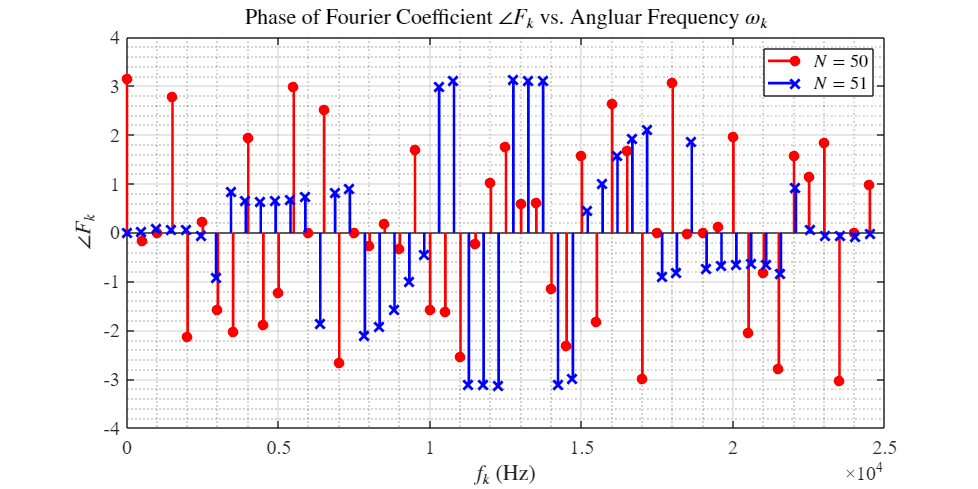

% Plot phase vs frequency (Hz).
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(f_k1, F_k1_phase, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(f_k2, F_k2_phase, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'b', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$f_k$ (Hz)', 'Interpreter', 'latex');
ylabel('$\angle F_k$', 'Interpreter', 'latex');
legend('$N = 50$', '$N = 51$', 'Interpreter', 'latex', 'Location', 'northeast');
title('Phase of Fourier Coefficient $\angle F_k$ vs. Angluar Frequency $\omega_k$', 'Interpreter', 'latex');

### Problem 4

***N***** = 50:** If the frequency components are discretized based on the true periodicity of the discrete time signal, the non-zero Fourier coefficients will only occur at the frequencies that are exactly the same as the harmonic frequencies.

***N***** = 51:** If the frequency components are discretized based on the number of samples of the discrete time signal,  all the Fourier coefficients will be non-zero. The peak magnitude values of the Fourier coefficients will occur around those harmonic frequencies. This is because those harmonic frequencies are not exactly involved in the discretized frequency components. The discrete time signal are decomposed to these frequency components and the magnitude of each frequency component will compensate with each other, resulting in non-zero magnitudes for all the frequency components.

### Problem 5

**Calculate the reconstructed samples by inverse DTFS for case 1 (*****N***** = 50):**

% Initialization for the reconstructed sample vector.
ReconstructedSamples1 = zeros(1,L);

% Calculate the reconstructed samples.
for n = 0:L-1
    for k = 0:N-1
        ReconstructedSamples1(n+1) = ReconstructedSamples1(n+1) + real(F_k1(k+1) * exp(1i*omega_k1(k+1)*n));
    end
end

**Calculate the reconstructed samples by inverse DTFS for case 2 (*****N***** = 51):**

% Initialization for the reconstructed sample vector.
ReconstructedSamples2 = zeros(1,L);

% Calculate the reconstructed samples.
for n = 0:L-1
    for k = 0:L-1
        ReconstructedSamples2(n+1) = ReconstructedSamples2(n+1) + real(F_k2(k+1) * exp(1i*omega_k2(k+1)*n));
    end
end

**Plot the reconstruction results:**

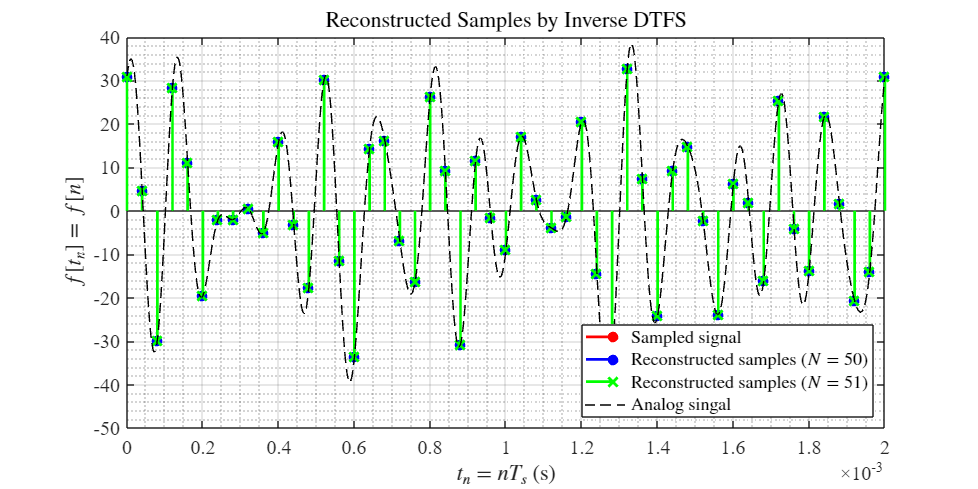

% Plot the analog signal, the sampled signal and the reconstructed samples.
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(SampledTimeVector, SampledSignal, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(SampledTimeVector, ReconstructedSamples1, 'MarkerFaceColor', 'b', 'Color', 'b', 'LineWidth', 2);
stem(SampledTimeVector, ReconstructedSamples2, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'g', 'LineWidth', 2);
plot(AnalogTimeVector, AnalogSignal, '--k');
grid on;
grid minor;
box on;
xlabel('$t_n=nT_s$ (s)', 'Interpreter', 'latex');
ylabel('$f[t_n]=f[n]$', 'Interpreter', 'latex');
legend('Sampled signal', 'Reconstructed samples ($N = 50$)', 'Reconstructed samples ($N = 51$)', 'Analog singal', 'Interpreter', 'latex', 'Location', 'southeast');
title('Reconstructed Samples by Inverse DTFS', 'Interpreter', 'latex');

**Calculate and plot the reconstruction error:**

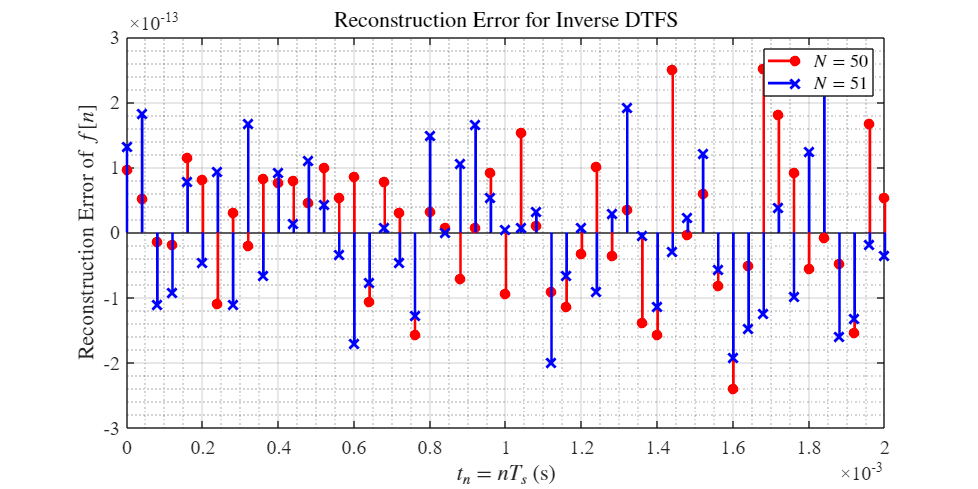

% Calculate the reconstruction error.
Error1 = ReconstructedSamples1 - SampledSignal;
Error2 = ReconstructedSamples2 - SampledSignal;

% Plot the reconstruction error.
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
hold on;
stem(SampledTimeVector, Error1, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(SampledTimeVector, Error2, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'b', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$t_n=nT_s$ (s)', 'Interpreter', 'latex');
ylabel('Reconstruction Error of $f[n]$', 'Interpreter', 'latex');
legend('$N = 50$', '$N = 51$', 'Interpreter', 'latex', 'Location', 'northeast');
title('Reconstruction Error for Inverse DTFS', 'Interpreter', 'latex');

### Problem 6

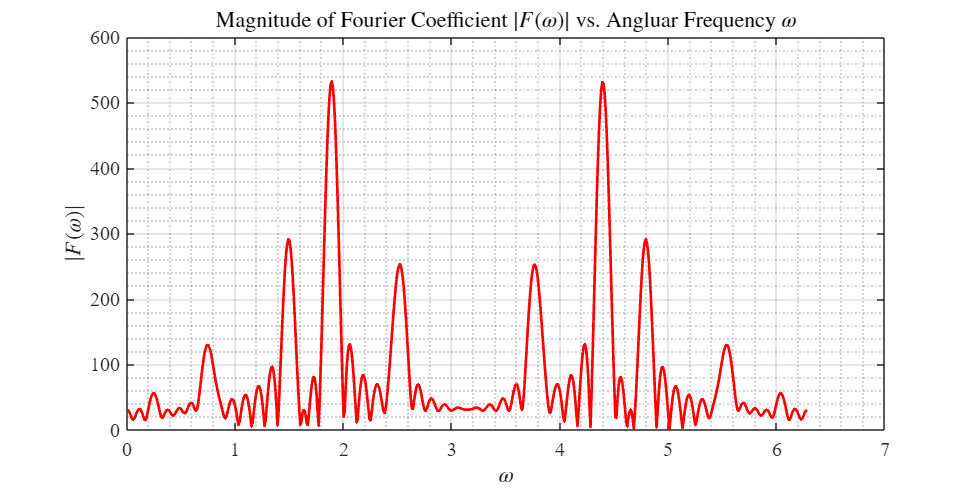

% Define the symbolic value omega for angular frequency.
syms omega

% Calculate the corresponding frequency in Hz.
f = omega / (2*pi) * f_s;

% Calculate the DTFT Fourier coefficients.
F_omega = 0; % Initialization.

for k1 = 0:length(SampledSignal)-1
    F_omega = F_omega + SampledSignal(k1+1) * exp(-i*omega*k1);
end

% Substitue the numerical values for the angular frequency and calculate the results.
omega = 0:(1/100):2*pi;
F_w_values = subs(F_omega);
f_values = subs(f);
F_w_magnitude = abs(F_w_values);

% Plot magnitude vs angular frequency.
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(omega, F_w_magnitude, 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$|F(\omega)|$', 'Interpreter', 'latex');
title('Magnitude of Fourier Coefficient $|F(\omega)|$ vs. Angluar Frequency $\omega$', 'Interpreter', 'latex');

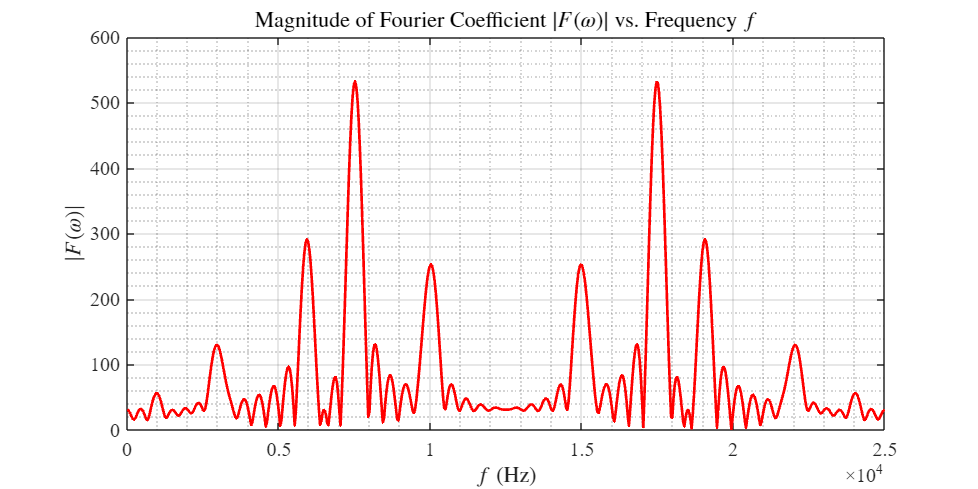

% Plot magnitude vs frequency (Hz).
figure();
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(f_values, F_w_magnitude, 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$f$ (Hz)', 'Interpreter', 'latex');
ylabel('$|F(\omega)|$', 'Interpreter', 'latex');
title('Magnitude of Fourier Coefficient $|F(\omega)|$ vs. Frequency $f$', 'Interpreter', 'latex');

### Problem 7

**Calculate the DFT by sampling the DTFT:**

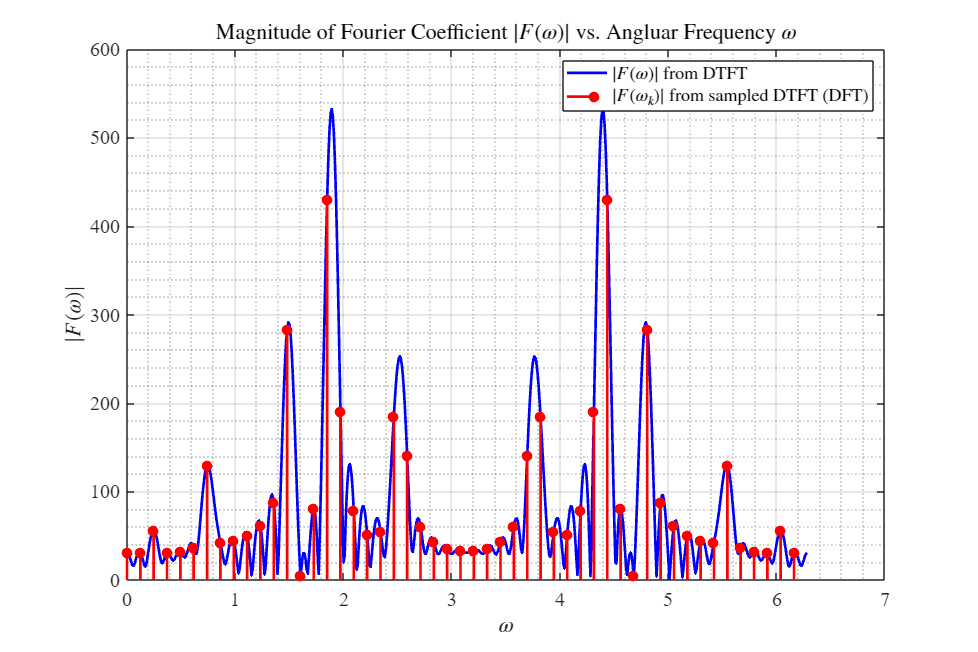

tic;

% Sampling DTFT with N samples.
N = L;
k1 = 0:1:N-1;
omega = (2*pi/N) * k1;
F_wk_values = subs(F_omega);

% Record the time for obtaining the samples of DTFT.
Time_DFT = toc;

% Calculate the magnitude of the sampled DTFT (DFT).
F_wk_magnitude = abs(F_wk_values);

% Plot the magnitude for the continuous DTFT and the sampled DTFT (DFT).
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(0:(1/100):2*pi, F_w_magnitude, 'Color', 'b', 'LineWidth', 2);
stem(omega, F_wk_magnitude, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$|F(\omega)|$', 'Interpreter', 'latex');
legend('$|F(\omega)|$ from DTFT', '$|F(\omega_k)|$ from sampled DTFT (DFT)','Interpreter', 'latex', 'Location', 'northeast');
title('Magnitude of Fourier Coefficient $|F(\omega)|$ vs. Angluar Frequency $\omega$', 'Interpreter', 'latex');

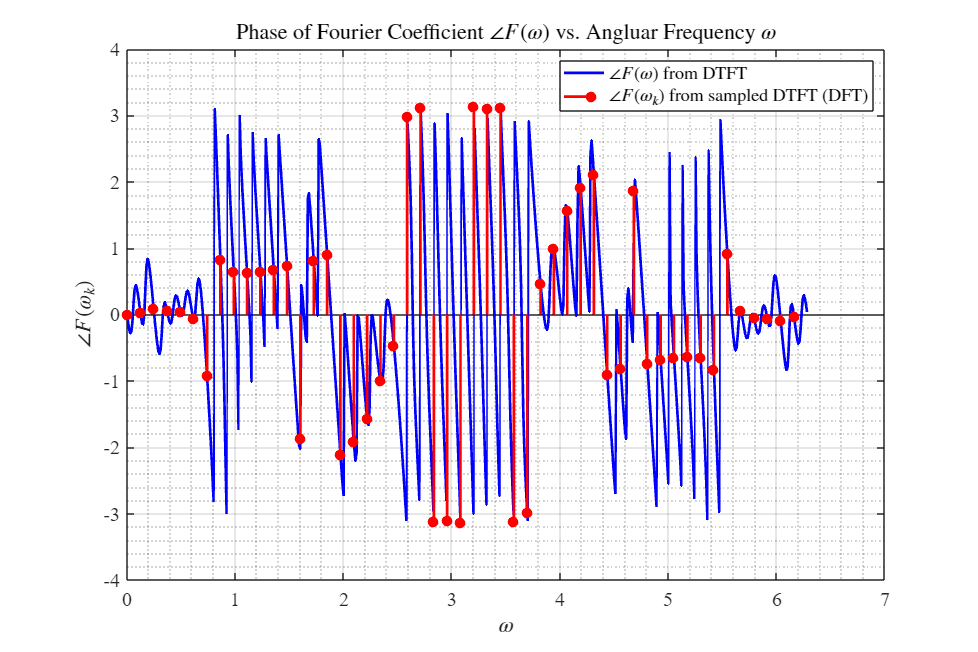

% Calculate the phase of continuous DTFT and sampled DTFT (DFT).
F_w_phase = angle(F_w_values);
F_wk_phase = angle(F_wk_values);

% Plot the phase for the continuous DTFT and the sampled DTFT (DFT).
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(0:(1/100):2*pi, F_w_phase, 'Color', 'b', 'LineWidth', 2);
stem(omega, F_wk_phase, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$\angle F(\omega_k)$', 'Interpreter', 'latex');
legend('$\angle F(\omega)$ from DTFT', '$\angle F(\omega_k)$ from sampled DTFT (DFT)','Interpreter', 'latex', 'Location', 'northeast');
title('Phase of Fourier Coefficient $\angle F(\omega)$ vs. Angluar Frequency $\omega$', 'Interpreter', 'latex');

**Time (seconds) required to obtain the DFT Fourier coefficients by sampling the DTFT:**

display(Time_DFT);

Time_DFT = 0.3462

### Problem 8

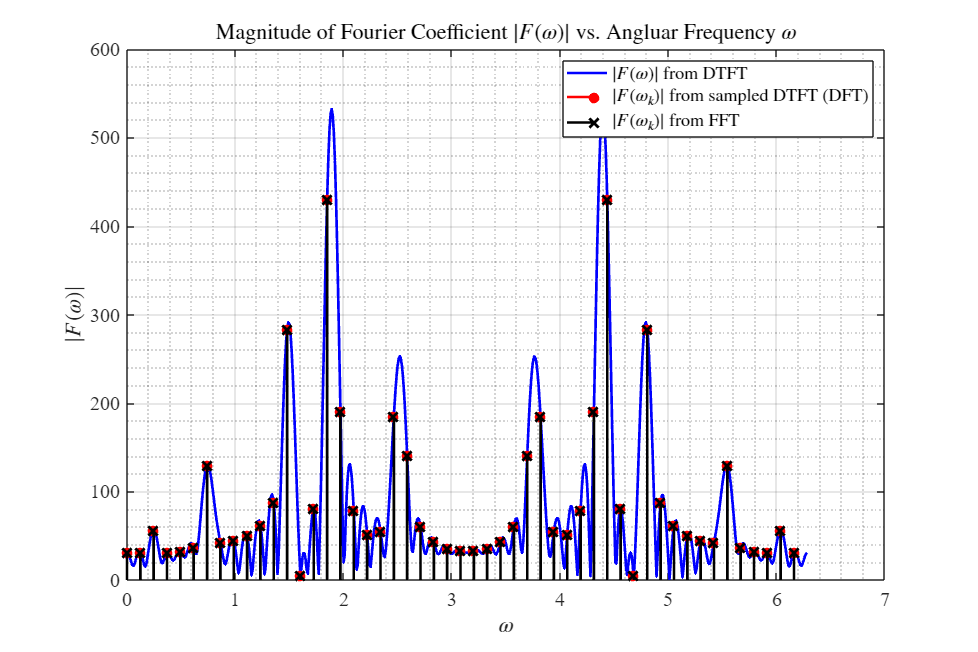

tic;

% Calculate DFT using the FFT algorithm, then extract the maginitude and phase.
F_fft_values = fft(SampledSignal, N);

% Record the time for obtaining the samples of FFT.
Time_FFT = toc;

% Calculate the magnitude and phase of the FFT.
F_fft_magnitude = abs(F_fft_values);
F_fft_phase = angle(F_fft_values);

% Plot the magnitude results.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(0:(1/100):2*pi, F_w_magnitude, 'Color', 'b', 'LineWidth', 2);
stem(omega, F_wk_magnitude, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(omega, F_fft_magnitude, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'k', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$|F(\omega)|$', 'Interpreter', 'latex');
legend('$|F(\omega)|$ from DTFT', '$|F(\omega_k)|$ from sampled DTFT (DFT)', '$|F(\omega_k)|$ from FFT', 'Interpreter', 'latex', 'Location', 'northeast');
title('Magnitude of Fourier Coefficient $|F(\omega)|$ vs. Angluar Frequency $\omega$', 'Interpreter', 'latex');

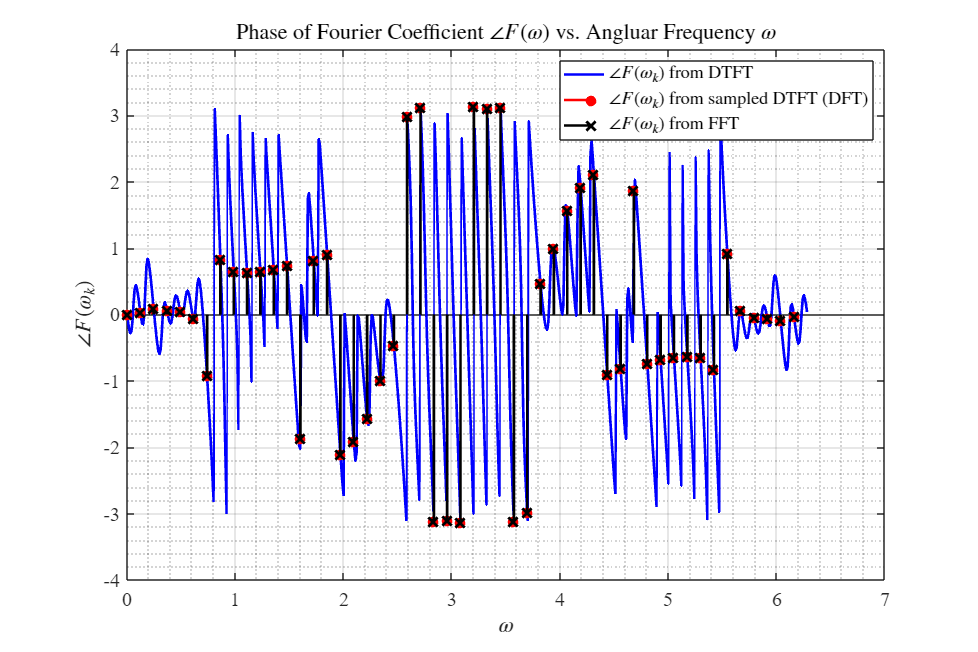

% Plot the phase results.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(0:(1/100):2*pi, F_w_phase, 'Color', 'b', 'LineWidth', 2);
stem(omega, F_wk_phase, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(omega, F_fft_phase, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'k', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$\angle F(\omega_k)$', 'Interpreter', 'latex');
legend('$\angle F(\omega_k)$ from DTFT', '$\angle F(\omega_k)$ from sampled DTFT (DFT)', '$\angle F(\omega_k)$ from FFT', 'Interpreter', 'latex', 'Location', 'northeast');
title('Phase of Fourier Coefficient $\angle F(\omega)$ vs. Angluar Frequency $\omega$', 'Interpreter', 'latex');

### **Problem 9**

**Time (seconds) required to obtain the DFT Fourier coefficients by FFT algorithm:**

display(Time_FFT);

Time_FFT = 0.0060

From the analysis, the time required to obatin the DFT Fourier coefficients by sampling DTFT and by FFT algorithm are 0.3462 second and 0.0060 second. Although the first time value is only for sampling DTFT (time for calculation of DTFT is not included), the FFT algorithm requires extremely less time compared to sampling the DTFT.

### Problem 10

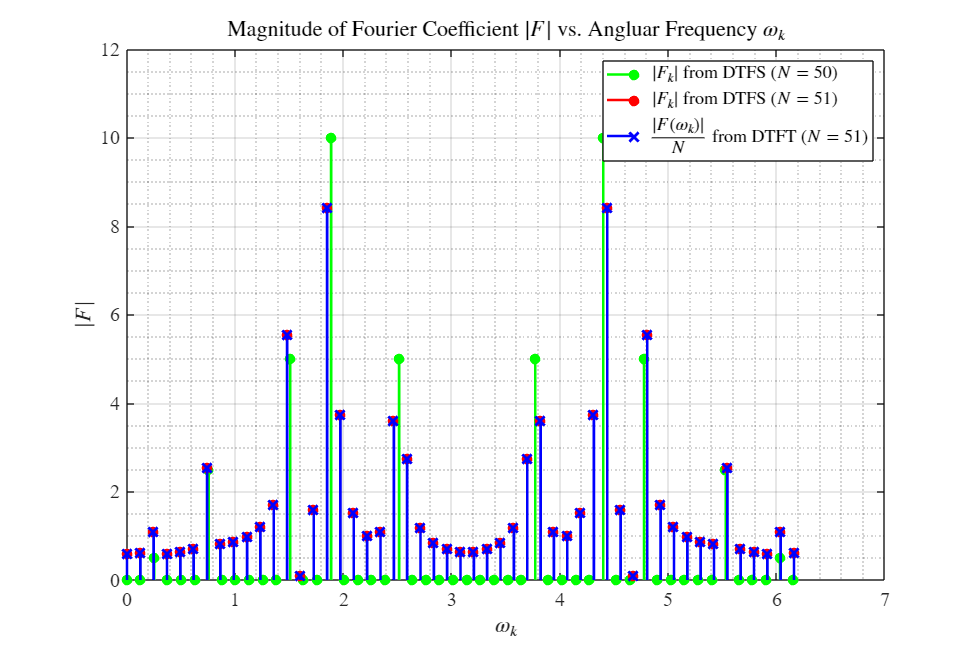

figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
stem(omega_k1, F_k1_magnitude, 'MarkerFaceColor', 'g', 'Color', 'g', 'LineWidth', 2);
stem(omega_k2, F_k2_magnitude, 'MarkerFaceColor', 'r', 'Color', 'r', 'LineWidth', 2);
stem(omega, F_wk_magnitude/L, 'Marker', 'x', 'MarkerSize', 10, 'Color', 'b', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$\omega_k$', 'Interpreter', 'latex');
ylabel('$|F|$', 'Interpreter', 'latex');
legend('$|F_k|$ from DTFS ($N = 50$)', '$|F_k|$ from DTFS ($N = 51$)', '$\frac{|F(\omega_k)|}{N}$ from DTFT ($N = 51$)', 'Interpreter', 'latex', 'Location', 'northeast');
title('Magnitude of Fourier Coefficient $|F|$ vs. Angluar Frequency $\omega_k$', 'Interpreter', 'latex');

When the number of discretized frequency components of DTFS and the number of samples in frequency domain of DTFT are both equal to the number of sample points (*N* = *L*), the DTFS magnitude is the DTFT magnitude at the omega_k value divided by *N*. For a discrete time signal with *L* samples, in order to avoid aliasing in the time domain, the number of samples N in the frequency domain must be greater or equal to the number of samples *L* in the time domain.

### Problem 11

**Read the data file:**

clear;
clc;
close all;

% Load the data from the .csv file.
data = load('Observations.csv');
data = data';
N = length(data);

**Calculate the discretized frequency components:**

% Create the index vector and calculate the discretized frequency components.
k1 = 0:1:N-1;
omega_k1 = (2*pi/N)*k1; % omega_k = Discretized angular frequency.
f_k_day = omega_k1 / (2*pi); % f_k_day = Discretized frequency in day^-1.
f_k_year = f_k_day * 365; % f_k_year = Discretized frequency in year^-1.

fprintf('The upper limit of frequency in day^-1: %f', max(f_k_day));

The upper limit of frequency in day^-1: 0.999812

fprintf('The lower limit of frequency in day^-1: %f', min(f_k_day));

The lower limit of frequency in day^-1: 0.000000

fprintf('The upper limit of frequency in year^-1: %f', max(f_k_year));

The upper limit of frequency in year^-1: 364.931288

fprintf('The lower limit of frequency in day^-1: %f', min(f_k_day));

The lower limit of frequency in day^-1: 0.000000

**Plot the discretized frequency components vs. index k:**

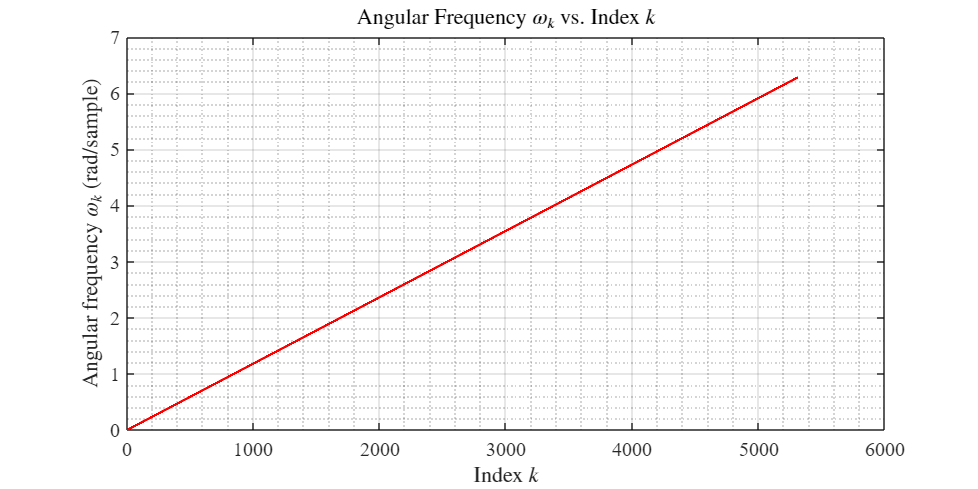

figure();
hold on;
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(k1, omega_k1, 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('Index $k$', 'Interpreter', 'latex');
ylabel('Angular frequency $\omega_k$ (rad/sample)', 'Interpreter', 'latex');
title('Angular Frequency $\omega_k$ vs. Index $k$', 'Interpreter', 'latex');

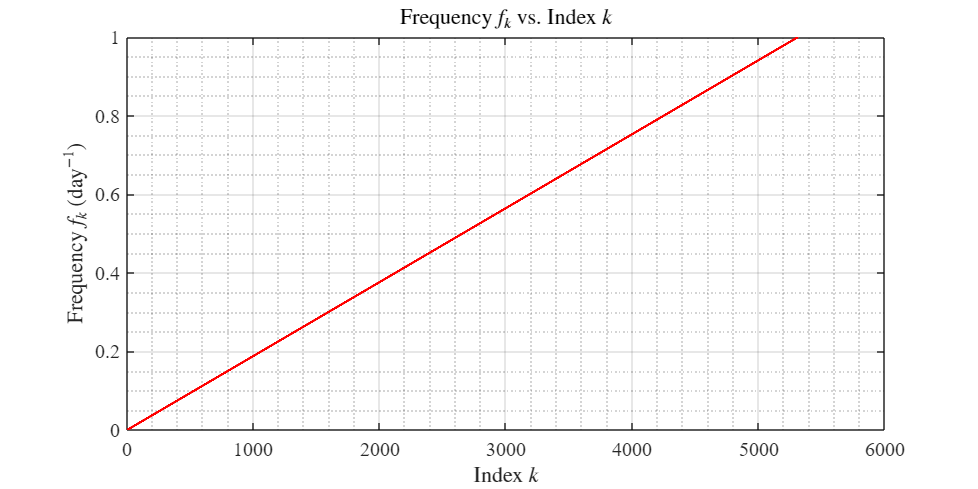

figure();
hold on;
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(k1, f_k_day, 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('Index $k$', 'Interpreter', 'latex');
ylabel('Frequency $f_k$ (day$^{-1}$)', 'Interpreter', 'latex');
title('Frequency $f_k$ vs. Index $k$', 'Interpreter', 'latex');

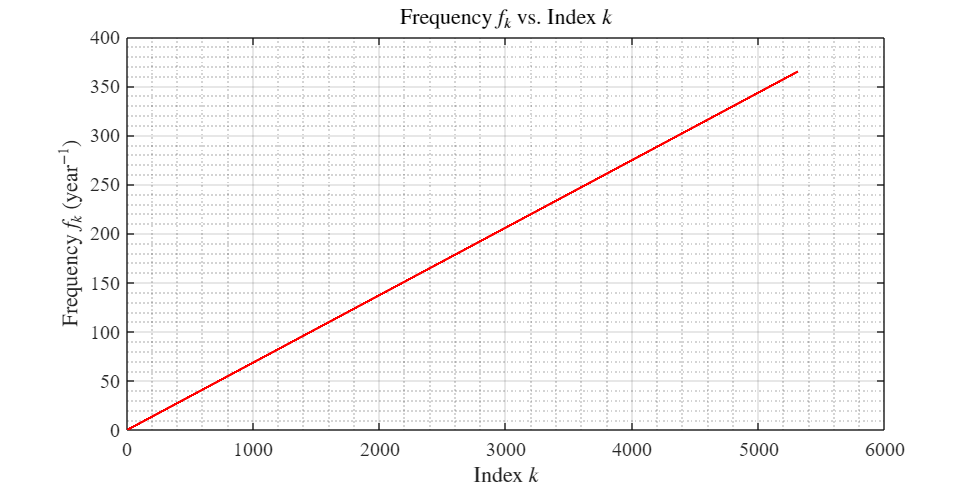

figure();
hold on;
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(k1, f_k_year, 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('Index $k$', 'Interpreter', 'latex');
ylabel('Frequency $f_k$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Frequency $f_k$ vs. Index $k$', 'Interpreter', 'latex');

### Problem 12

**Calculate the N-point FFT for the signal:**

% Calculate the N-point FFT for the signal.
data_FFT = fft(data, N);

% Calculate the magnitude and energy spectral density.
data_FFT_magnitude = abs(data_FFT);
data_FFT_energy = data_FFT_magnitude.^2;

**Plot energy density spectrum:**

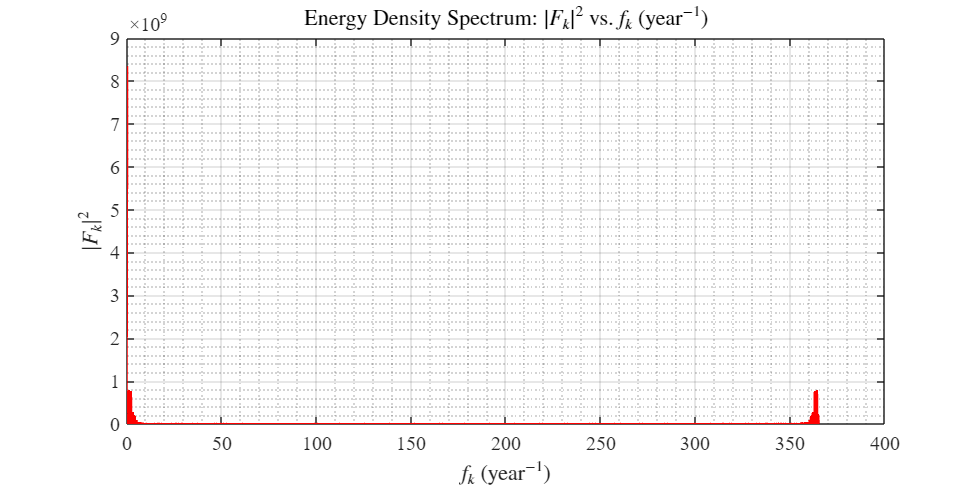

figure();
hold on;
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(f_k_year, data_FFT_energy, 'Color', 'r', 'LineWidth', 2);
grid on;
grid minor;
box on;
xlabel('$f_k$ (year$^{-1}$)', 'Interpreter', 'latex');
ylabel('$|F_k|^2$', 'Interpreter', 'latex');
title('Energy Density Spectrum: $|F_k|^2$ vs. $f_k$ (year$^{-1}$)', 'Interpreter', 'latex');

**Restrict the frequency as less or equal to 12:**

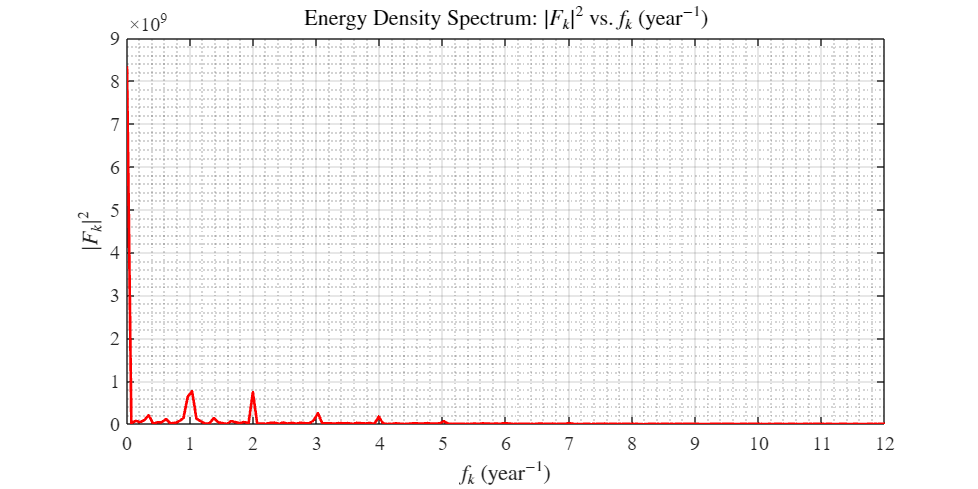

figure();
hold on;
set(gcf, 'Position',[0 0 1200 600]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);
plot(f_k_year, data_FFT_energy, 'Color', 'r', 'LineWidth', 2);
xlim([0, 12]);
xticks(0:1:12);
grid on;
grid minor;
box on;
xlabel('$f_k$ (year$^{-1}$)', 'Interpreter', 'latex');
ylabel('$|F_k|^2$', 'Interpreter', 'latex');
title('Energy Density Spectrum: $|F_k|^2$ vs. $f_k$ (year$^{-1}$)', 'Interpreter', 'latex');

The first 3 dominant frequencies in the signal: 0/year, 1/year and 2/year.

**0/year:** The most dominant frequency component of the signal is 0/year. This means there is a constant term in the river discharge, which does not change with the time.

**1/year:** The signal has a period of 1 year, which represents the change of the river discharge based on seasonal change every year.

**2/year:** The signal has a period of half year, which represents there are two cycles of rainfall or other factors that affect the river dischage every year.

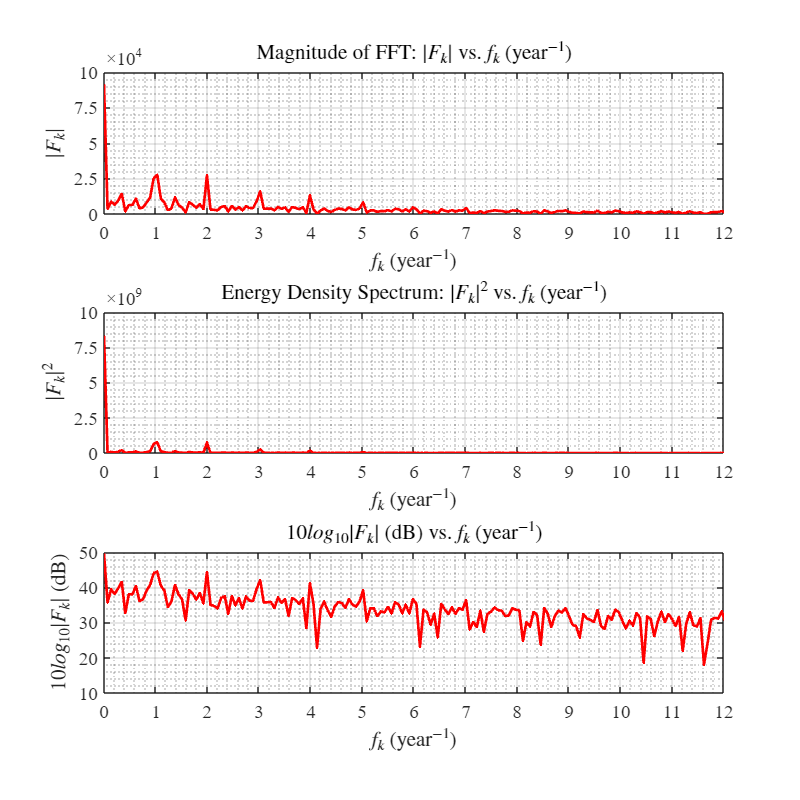

% Plot the results.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 1200]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);

subplot(3,1,1)
plot(f_k_year, data_FFT_magnitude, 'Color', 'r', 'LineWidth', 2);
xlim([0, 12]);
xticks(0:1:12);
yticks(0:2.5e+4:10e+4);
grid on;
grid minor;
box on;
xlabel('$f_k$ (year$^{-1}$)', 'Interpreter', 'latex');
ylabel('$|F_k|$', 'Interpreter', 'latex');
title('Magnitude of FFT: $|F_k|$ vs. $f_k$ (year$^{-1}$)', 'Interpreter', 'latex');

subplot(3,1,2)
plot(f_k_year, data_FFT_energy, 'Color', 'r', 'LineWidth', 2);
xlim([0, 12]);
xticks(0:1:12);
yticks(0:2.5e+9:10e+9);
grid on;
grid minor;
box on;
xlabel('$f_k$ (year$^{-1}$)', 'Interpreter', 'latex');
ylabel('$|F_k|^2$', 'Interpreter', 'latex');
title('Energy Density Spectrum: $|F_k|^2$ vs. $f_k$ (year$^{-1}$)', 'Interpreter', 'latex');

subplot(3,1,3)
plot(f_k_year, 10*log10(data_FFT_magnitude), 'Color', 'r', 'LineWidth', 2);
xlim([0, 12]);
xticks(0:1:12);
ylim([10, 50]);
yticks(10:10:50);
grid on;
grid minor;
box on;
xlabel('$f_k$ (year$^{-1}$)', 'Interpreter', 'latex');
ylabel('$10log_{10}|F_k|$ (dB)', 'Interpreter', 'latex');
title('$10log_{10}|F_k|$ (dB) vs. $f_k$ (year$^{-1}$)', 'Interpreter', 'latex');

The 3 FFT plot represent the contribution of each frequency in the discrete time signal.

**Magnitude plot:** It can show the variation more clearly when the magnitude values are less than 1.

**Energy density spectrum plot:** It can show the variation more clearly when the magnitude values are greater than 1, since the square of the magnitude can enlarge the differences between each values.

**Log scale plot:** Although it decrease the overall variance among all the values, it can enlarge the difference for some region that variance can not be clearly seen in the magnitude plot or the energy density spectrum plot.

### **Problem 13**

**Spectrogram plot:**

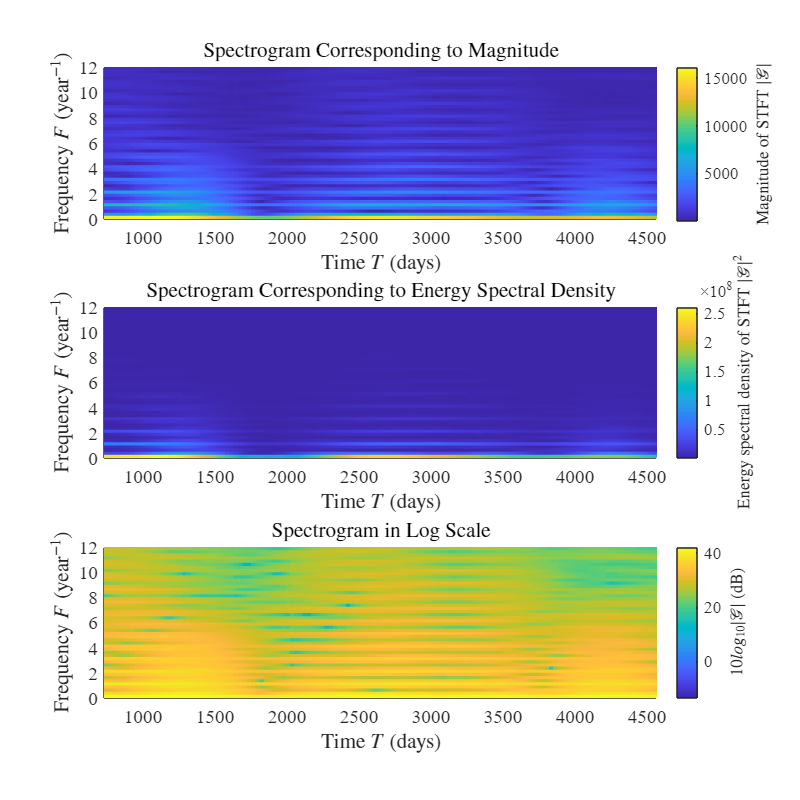

window_size = 365*4; % Window length.
n_overlap = 365*4-30; % Overlap sample size.
n_fft = 365*4; % Number of FFT samples.
f_s = 1; % Sampling frequency = 1/day.

% Obtain the spectrogram.
[S, F, T] = spectrogram(data, window_size, n_overlap, n_fft, f_s);

F = F * 365; % Convert frequency F from day^-1 to year^-1.

% Plot the spectrogram.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 1200]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);

subplot(3,1,1)
surface(T, F, abs(S), 'EdgeColor', 'none');
axis tight;
box on;
ylim([0, 12]);
yticks(0:2:12);
view(0, 90);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Spectrogram Corresponding to Magnitude', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Magnitude of STFT $|\mathcal{G}|$', 'Interpreter', 'latex');

subplot(3,1,2)
surface(T, F, abs(S).^2, 'EdgeColor', 'none');
axis tight;
box on;
ylim([0, 12]);
yticks(0:2:12);
view(0, 90);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Spectrogram Corresponding to Energy Spectral Density', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Energy spectral density of STFT $|\mathcal{G}|^2$', 'Interpreter', 'latex');

subplot(3,1,3)
surface(T, F, 10*log10(abs(S)), 'EdgeColor', 'none');
axis tight;
box on;
ylim([0, 12]);
yticks(0:2:12);
view(0, 90);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Spectrogram in Log Scale', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, '$10log_{10}|\mathcal{G}|$ (dB)', 'Interpreter', 'latex');

**Waterfall plot:**

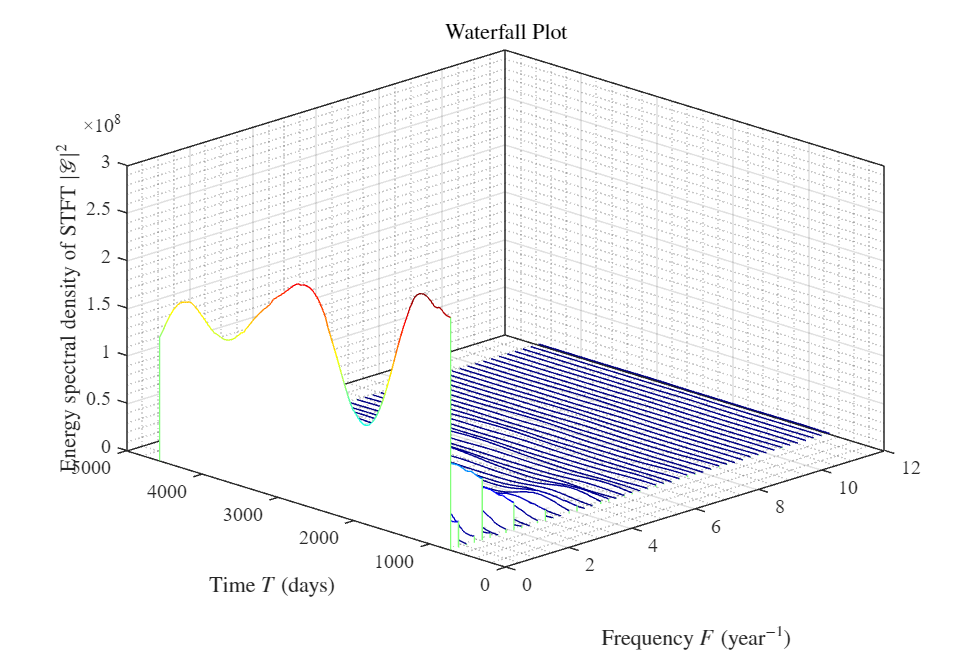

% Waterfall plot.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1], XDir='reverse', View=[45,30]);

waterfall(T, F, abs(S).^2);
colormap(jet);
grid on;
grid minor;
box on;
ylim([0, 12]);
yticks(0:2:12);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
zlabel('Energy spectral density of STFT $|\mathcal{G}|^2$', 'Interpreter', 'latex')
title('Waterfall Plot', 'Interpreter', 'latex');

**Interpretation of spectrogram and waterfall plot:**

The spectrogram shows how the magnitude of each frequency component change with time. The waterfall plot shows the same thing in the 3-D version. In the spectrogram plot of the river discharge, the yellow line at the bottom represents the components with frequencies close to 0, which are corresponding to the constant term in the river discharge not changing with the time. There are multiple yellow line above the bottom line (eg. at *F* = 1/year, 2/year) representing the other dominating frequencies in the signal. From the waterfall plot, the change of energy density for each frequency component with time can be observed more clearly. For example, a decrease is observed at *T* = 1500 - 2000 days for the energy density of most of the frequency components, resulting in a reduction in the total river discharge in that period, which can also be seen in the given river discharge plot in the time domain.

### Problem 14

**Wavelet transform:**

% Wavelet transform.
[cfs, frq, scales] = cwt(data, f_s);

% Create the sampled time vector.
t = 0:1:length(data)-1;

% Convert the frequency from day^-1 to year^-1.
frq = frq * 365;

**Wavelet plot without limit in frequency:**

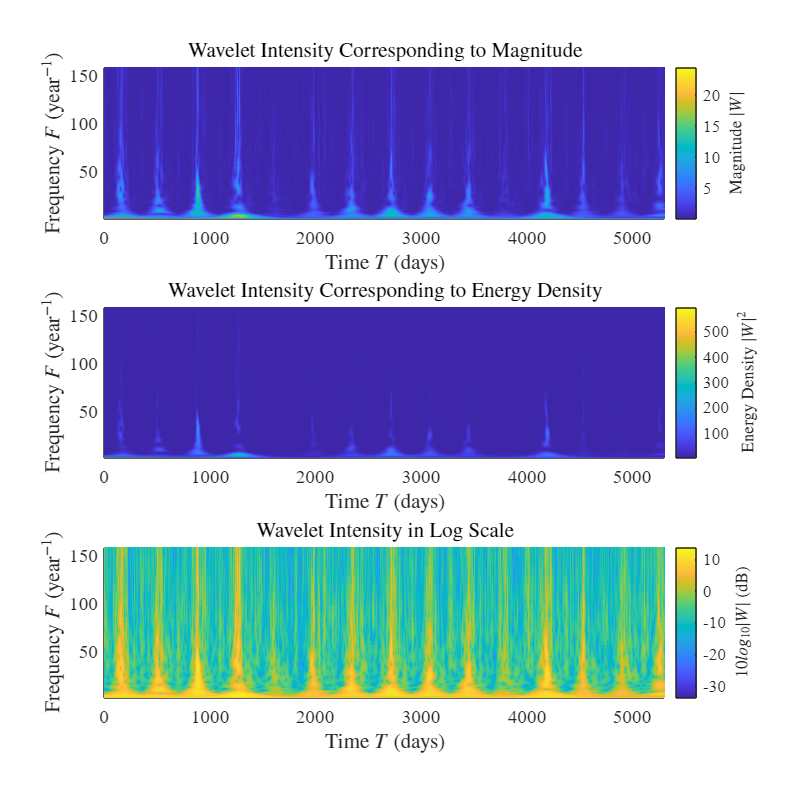

% Wavelet plot.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 1200]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);

subplot(3,1,1)
surface(t, frq, abs(cfs), 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Wavelet Intensity Corresponding to Magnitude', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Magnitude $|W|$', 'Interpreter', 'latex');

subplot(3,1,2)
surface(t, frq, abs(cfs).^2, 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Wavelet Intensity Corresponding to Energy Density', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Energy Density $|W|^2$', 'Interpreter', 'latex');

subplot(3,1,3)
surface(t, frq, 10*log10(abs(cfs)), 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Wavelet Intensity in Log Scale', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, '$10log_{10}|W|$ (dB)', 'Interpreter', 'latex');

**Wavelet plot with frequency limit to 12/year:**

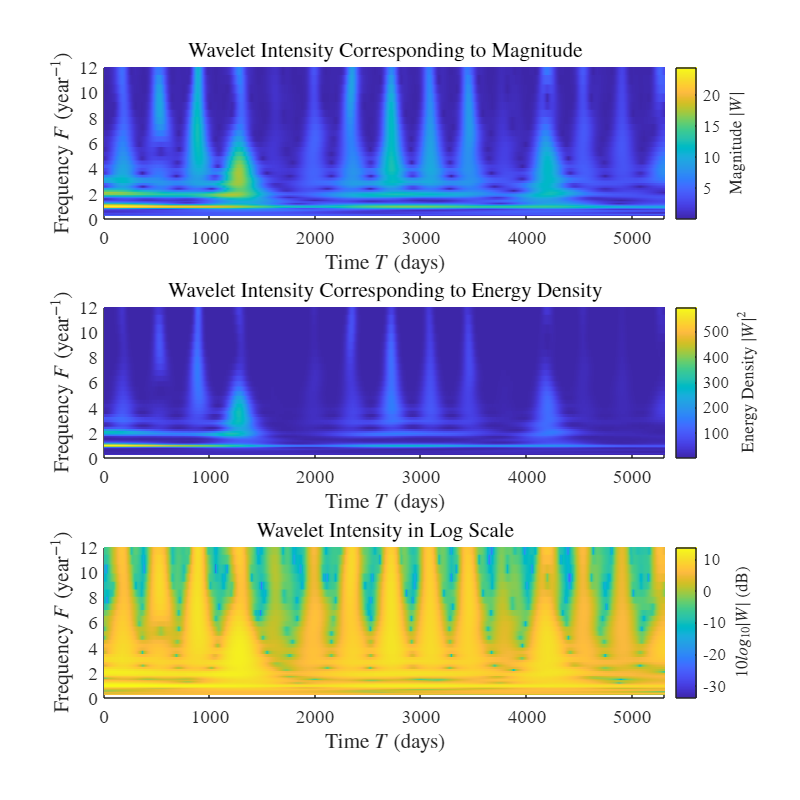

% Wavelet plot.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 1200]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);

subplot(3,1,1)
surface(t, frq, abs(cfs), 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
ylim([0, 12]);
yticks(0:2:12);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Wavelet Intensity Corresponding to Magnitude', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Magnitude $|W|$', 'Interpreter', 'latex');

subplot(3,1,2)
surface(t, frq, abs(cfs).^2, 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
ylim([0, 12]);
yticks(0:2:12);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Wavelet Intensity Corresponding to Energy Density', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Energy Density $|W|^2$', 'Interpreter', 'latex');

subplot(3,1,3)
surface(t, frq, 10*log10(abs(cfs)), 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
ylim([0, 12]);
yticks(0:2:12);
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
title('Wavelet Intensity in Log Scale', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, '$10log_{10}|W|$ (dB)', 'Interpreter', 'latex');

**Waterfall plot without frequency limit**:

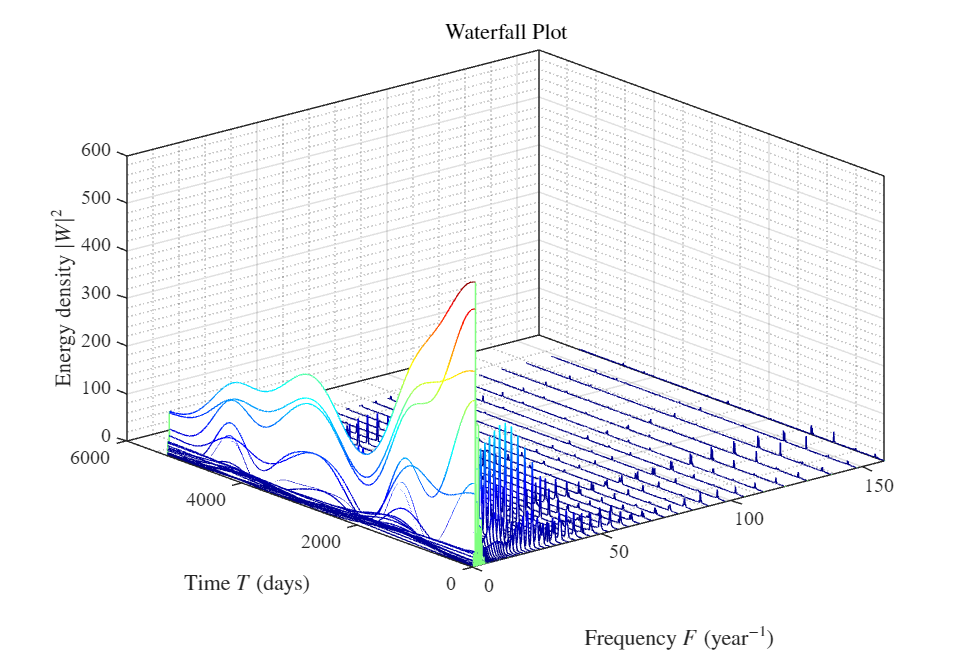

% Waterfall plot.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1], XDir='reverse', View=[50,30]);

waterfall(t, frq, abs(cfs).^2);
colormap(jet);
grid on;
grid minor;
box on;
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
zlabel('Energy density $|W|^2$', 'Interpreter', 'latex')
title('Waterfall Plot', 'Interpreter', 'latex');

**Waterfall plot with frequency limit to 12/year:**

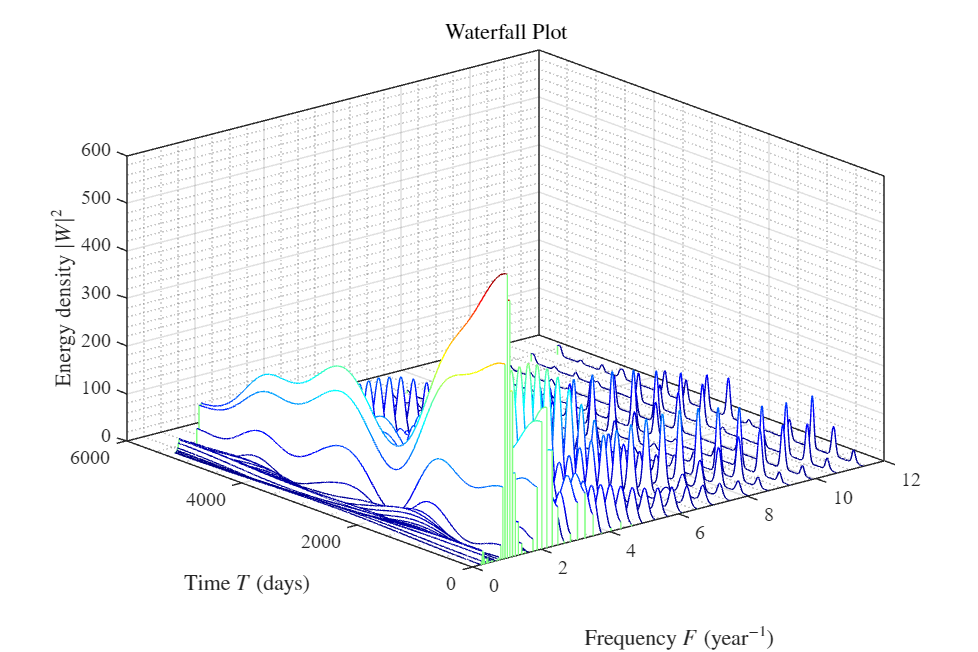

% Waterfall plot.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1], XDir='reverse', View=[50,30]);

waterfall(t, frq, abs(cfs).^2);
ylim([0, 12]);
yticks(0:2:12);
colormap(jet);
grid on;
grid minor;
box on;
xlabel('Time $T$ (days)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (year$^{-1}$)', 'Interpreter', 'latex');
zlabel('Energy density $|W|^2$', 'Interpreter', 'latex')
title('Waterfall Plot', 'Interpreter', 'latex');

**Discussion:**

**River discharge:** The spectrogram shows how the magnitude of each frequency component change with time. The waterfall plot shows the same thing in the 3-D version. Similar to the STFT results, in the spectrogram plot of the river discharge, the yellow color at the bottom represents the components with frequencies close to 0, which are corresponding to the constant term in the river discharge not changing with the time. There are multiple yellow line above the bottom line (eg. at *F* = 1/year, 2/year) representing the other dominating frequencies in the signal. Compared to the STFT results, the total discharge of the river can be observed more clearly from the wavelet analysis, especially from the log scale spectrogram plot. Multiple region with large wavelet intensity for most of the frequency components are observed in the log scale spectrogram plot, which leads to a large total discharge of the river.

**Uncertainty principle & Difference between STFT and wavelet analysis:** Time-frequency uncertainty principle limits the ability to simultaneously obtain the high resolution in both time and frequency domain. The spectrogram of STFT can provide both time and frequency information, but both in low resolutions. Since the STFT uses a fixed window size, its resolutions for time and frequency domain are limited by this window size. If a small window size is applied, there will be a good time resolution because the uncertainty in the time domain is small (the output is always at the center of the window, so the exact time information is lost). However, this leads to a poor frequency resolution since a small window size can only provide limited number of samples. Inversely, if a large window size is applied, there will be a good frequency resolution because of large number of samples and a poor time resolution due to the large uncertainty in time domain. In the waterfall plot of STFT, the fixed window size can be observed by the same interval between each line along the frequency axis.

The wavelet analysis applies diffrent resolution in time and frequency domain for different frequency components (multi-resolution) by changing the scale parameter *s* in the equation. The scale parameter is the inverse of frequency value and it is used to scale the width of wavelet. For the low frequencies, the scale parameter is large, which leads to the large wavelet width (similar to large window size in STFT). As a result, there will be good frequency resolution but poor time resolution. Inversely, there will be poor frequency resolution but good time resolution for high frequencies. In the waterfall plot, it can be observed that the intervals between each line along frequency axis are small at low frequencies, and the intervals increase as the frequency increases.

When comparing the high frequency part of waterfall plots obtained from STFT and wavelet analysis, we can observe almost no oscillation in the STFT result but some oscillations in the wavelet analysis result. This is because the wavelet analysis provides higher resolution in time domain for high frequency components compared to STFT. So more details can be observed for the change in time domain.

### Problem 15

**Read the file and cut it to a shorter period for analysis:**

clear;
clc;
close all;

% Read the song file.
[Data, SampleRate] = audioread('KeyNG.mp3');
Duration = size(Data,1) / SampleRate; % Total duration of the song in seconds.
t = linspace(0, Duration, size(Data,1)); % Create a vector for the timestamps.

% Cut the song to a shorter period for analysis.
Data2 = Data(4110000:5292000,1); % Extract a period in the 1st channel for analysis.
player = audioplayer(Data2, SampleRate);
play(player);

**Spectrogram of STFT:**

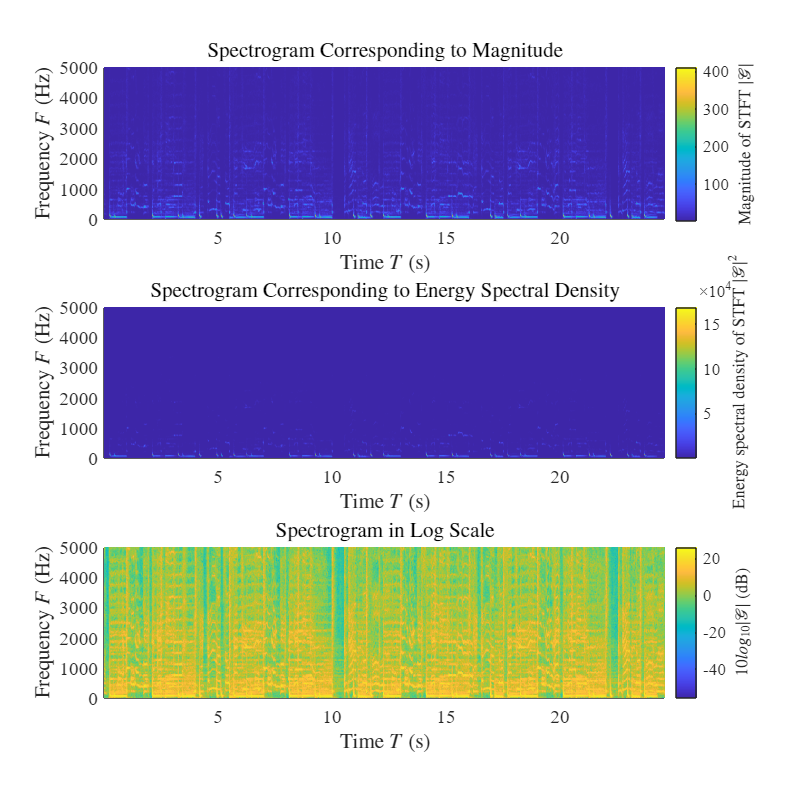

window_size = 2000; % Window length.
n_overlap = 1000; % Overlap sample size.
n_fft = 2000; % Number of FFT samples.
f_s = SampleRate; % Sampling frequency.

% Obtain the spectrogram.
[S, F, T] = spectrogram(Data2, window_size, n_overlap, n_fft, f_s);

% Plot the spectrogram.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 1200]);
set(gca, 'units','normalized','outerposition',[0 0 1 1]);

subplot(3,1,1)
surface(T, F, abs(S), 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
ylim([0, 5000]);
yticks(0:1000:5000);
xlabel('Time $T$ (s)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (Hz)', 'Interpreter', 'latex');
title('Spectrogram Corresponding to Magnitude', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Magnitude of STFT $|\mathcal{G}|$', 'Interpreter', 'latex');

subplot(3,1,2)
surface(T, F, abs(S).^2, 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
ylim([0, 5000]);
yticks(0:1000:5000);
xlabel('Time $T$ (s)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (Hz)', 'Interpreter', 'latex');
title('Spectrogram Corresponding to Energy Spectral Density', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, 'Energy spectral density of STFT $|\mathcal{G}|^2$', 'Interpreter', 'latex');

subplot(3,1,3)
surface(T, F, 10*log10(abs(S)), 'EdgeColor', 'none');
axis tight;
box on;
view(0, 90);
ylim([0, 5000]);
yticks(0:1000:5000);
xlabel('Time $T$ (s)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (Hz)', 'Interpreter', 'latex');
title('Spectrogram in Log Scale', 'Interpreter', 'latex');
colorbar;
ylabel(colorbar, '$10log_{10}|\mathcal{G}|$ (dB)', 'Interpreter', 'latex');

**Waterfall plot for STFT:**

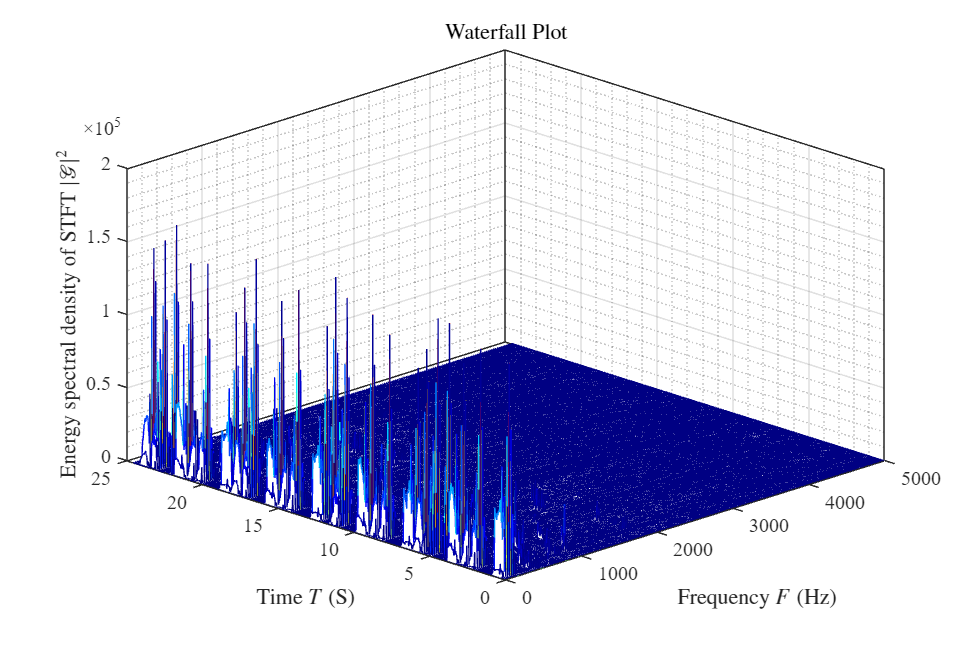

% Waterfall plot.
figure();
hold on;
set(gcf, 'Position',[0 0 1200 800]);
set(gca, 'units','normalized','outerposition',[0 0 1 1], XDir='reverse', View=[45, 30]);

waterfall(T, F, abs(S).^2);
colormap(jet);
grid on;
grid minor;
box on;
ylim([0, 5000]);
yticks(0:1000:5000);
xlabel('Time $T$ (S)', 'Interpreter', 'latex');
ylabel('Frequency $F$ (Hz)', 'Interpreter', 'latex');
zlabel('Energy spectral density of STFT $|\mathcal{G}|^2$', 'Interpreter', 'latex')
title('Waterfall Plot', 'Interpreter', 'latex');

**Observations:**

The spectrogram and waterfall plots are obtained from an approximate 25 seconds duration of channel-1 from the original .mp3 file. The total number of the data points in the duration is 1182000. The result is obtained using window size of 2000 data points with 1000 points overlap. The number of samples in DTF is 2000. The output results have a limit in frequency component between 0 and 5000 Hz.

From the spectrogram and waterfall plots, it is observed that the dominant frequency component of the signal is less than 1000 Hz. The pause (background music only) can be clearly observed from the plots as the region with low magnitude or energy density. Also, two singers (one man and one woman) are involved in this song. The parts from the woman singer (with approximate timestamps 2.5s - 5s, 7.5s - 10s, 14s - 17s and 20s - 22.5s) have similar rythm, and this can be observed by a similar trend in waterfall plot in those time durations.